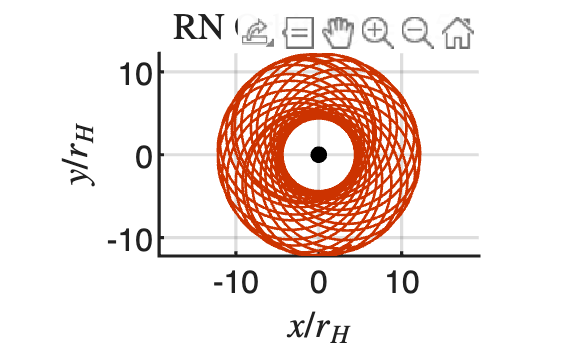

  %RN黑洞进动轨道
    clear; clc; 
    close all; 
    
    % 物理参数
    M = 1;              
    Q = 0.5;            
    r_h = M + sqrt(M^2 - Q^2);    
    
    % 初始条件
    r_0 = 12 * M;       
    L = 4.0 * M;        
    E = 0.97;           
    
    % 初始动量计算
    f_func = @(r) 1 - 2*M./r + Q^2./r.^2;
    f_0 = f_func(r_0);
    term = (E^2/f_0 - 1 - L^2/r_0^2) / f_0;
    
    if term < 0
        error('在势垒禁止区');
    end
    pr_0 = sqrt(term);    
    
    u0 = [0; r_0; pi/2; 0; -E; pr_0; 0; L];
    
    % 符号推导
    t = sym('t', 'real');
    r = sym('r', 'real');
    th = sym('th', 'real');
    ph = sym('ph', 'real');
    pt = sym('pt', 'real');
    pr = sym('pr', 'real');
    pth = sym('pth', 'real');
    pph = sym('pph', 'real');
    tau = sym('tau', 'real');
    
    % 度规函数 & 哈密顿量
    f_s = 1 - 2*M/r + Q^2/r^2;
    g_up = diag([-1/f_s, f_s, 1/r^2, 1/(r^2*sin(th)^2)]);
    H_sym = 0.5 * [pt pr pth pph] * g_up * [pt; pr; pth; pph];
    
    % 正则方程
    vars = [t; r; th; ph; pt; pr; pth; pph];
    eqs = [diff(H_sym, pt);
           diff(H_sym, pr);
           diff(H_sym, pth);
           diff(H_sym, pph);
           -diff(H_sym, t);
           -diff(H_sym, r);
           -diff(H_sym, th);
           -diff(H_sym, ph)];
           
    odefun = matlabFunction(eqs, 'Vars', {tau, vars});

    %  数值模拟
    options = odeset('RelTol', 1e-9, 'AbsTol', 1e-12, ...
                     'Events', @(t,u) stop_at_horizon(t, u, r_h));

    [~, sol] = ode45(odefun, [0 10000], u0, options);

    % 绘图 
    r_sol = real(sol(:, 2));
    phi_sol = real(sol(:, 4));
    
    r_norm = r_sol ./ r_h; 
    x_norm = r_norm .* cos(phi_sol);
    y_norm = r_norm .* sin(phi_sol);

    fig = figure('Color', 'w', 'Name', 'RN Orbit Corrected'); 
    ax = axes('Parent', fig); hold(ax, 'on');

    % 绘制轨道
    plot(x_norm, y_norm, 'Color', [0.8 0.2 0], 'LineWidth', 1.0, 'Parent', ax);
    
    % 绘制黑洞视界
    rectangle('Position', [-1, -1, 2, 2], 'Curvature', [1, 1], ...
              'FaceColor', 'k', 'EdgeColor', 'none', 'Parent', ax);

    % 美化设置
    axis(ax, 'equal'); 
    grid(ax, 'on');
    set(ax, 'FontSize', 12, 'LineWidth', 1.2); 
   
    xlabel(ax, '$x / r_H$', 'Interpreter', 'latex', 'FontSize', 14); 
    ylabel(ax, '$y / r_H$', 'Interpreter', 'latex', 'FontSize', 14);
    title(ax, ['RN Orbit ($Q=' num2str(Q) '$)'], 'Interpreter', 'latex', 'FontSize', 14);



% 事件函数设置
function [value, isterminal, direction] = stop_at_horizon(~, u, r_h_val)
    r_current = u(2);
    value = r_current - 1.01 * r_h_val; 
    isterminal = 1; 
    direction = -1; 
end